# Search for fluorophores based on 500-600nm data

We ask whether we can find three fluorophores defined as Skewed Gaussians, one of which has blood applied to it, that can fit the lip and tongue data. 

We find the parameters for the skewed Gaussian using for the range 500-600 nm

- create fluorophore structure for FAD and NADH from data/sources/Wu&Qu

- fit positively-skewed gaussian distribution to  collagen, keratin, FAD and NADH (all from Wu&Qu data)

- Use mean and std of FAD,NADH and blood-attenuated collagen as starting functions to fit lip data 

- use a) the best-fitting basis functions from Step 3, and b) the mean and std dev of keratin as starting function, to fit tongue data 

Another thing to try is for range 500-700 nm

- use mean and std of FAD,NADH and blood-attenuated collagen from Step 3 of 500-600 nm (above) as starting functions to fit lip data (over range of 500-700 nm)

- use mean and std of FAD,NADH and blood-attenuated collagen from Step 1 of 500-700 nm, AND mean and std of keratin from Step 4 of 500-600 nm, AND porphyrins and chlorophyll as spectral basis functions to fit tongue data

See also:  s_oeBloodFluorophoreTongueSrch.mlx, s_oeBloodFluorophoreLip.srch.mlx

## Initialize

ieInit;
wave = 500:600;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
[T,dataDir] = oeDatabaseCreate;
subjects = {'Z','B','D','J'};

oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);
oxyblood.opticalDensity = 15;
oxyTransmittance = oxyblood.transmittance;

## Fit all the subjects at once for both tongue and lip

The goal is to have the same fluorophores for all the fitting, and that we allow the weights, but not the fluorophores to vary.

We fix the blood density above, too.  In some of the other scripts we searched for effective blood density.  These differed between tongue and lip but here it seems the impact is not that large.

Here are the data for tongue, lip and all subjects.

Tfiles405 = ieTableGet(T,'substrate','tongue','e wave',405);
Tfiles415 = ieTableGet(T,'substrate','tongue','e wave',415);
Tnum = size(Tfiles405,1) + size(Tfiles415,1);

Lfiles405 = ieTableGet(T,'substrate','lip','e wave',405);
Lfiles415 = ieTableGet(T,'substrate','lip','e wave',415);
Lnum = size(Lfiles405,1) + size(Lfiles415,1);

allFiles = cat(1,Tfiles405,Tfiles415,Lfiles405,Lfiles415);
allData = oeReadFiles(allFiles,'normalized wave',normWave,'wave',wave);
assert(size(allFiles,1) - (Lnum + Tnum) == 0);

% plot(wave,oxyTransmittance);

Find the parameters, weights and skewedG has the fluorophores and the blood.

[global_params, wgtsNN, skewedG] = ...
    oeSolveFluorophoresSkewedGaussians(wave, allData, oxyTransmittance);
disp('Optimized Gaussian Parameters:');

Optimized Gaussian Parameters:


name = {'collagen','keratin','FAD   '};
for ii=1:3
    fprintf('%s - Peak: %.1f Spread: %.1f Skew: %.1f\n',name{ii},global_params(ii:3:end));
end

collagen - Peak: 402.9 Spread: 94.8 Skew: -1.5
keratin - Peak: 504.8 Spread: 38.8 Skew: 0.2
FAD    - Peak: 578.6 Spread: 69.8 Skew: 0.0



% Plot these in 3-space to see if they cluster, which they must
disp('Non-Negative Tongue Weights');

Non-Negative Tongue Weights


tongueWeights = wgtsNN(:,1:Tnum);
disp(tongueWeights)

    3.5190    3.8478    3.7607    3.1562    3.0319    2.7204    3.4817    4.7601    3.4436    3.9900    3.8734    3.7767    4.2466    5.5932    4.9435    5.2038    4.9541    5.3676    4.7419    5.0908    4.8153    2.3395    2.4081    2.2832    2.5939    2.3358    2.2861    2.5331    3.4456    2.8585    2.7550    2.8450    3.2748    2.5490    2.8284    2.8133    2.1626    3.0973    3.1582    3.1656    3.2907    2.9707    2.8312    3.2308    3.1621    3.4721    3.3862    3.0996    2.9728    3.1944    2.4671    2.9944    2.7428    2.9256    3.2433    3.6333    2.3983    2.4523    2.4602    4.3822    3.8243    4.2575    3.4225    3.7624    3.5609    2.5168
    0.7288    0.7122    0.7557    0.8127    0.8084    0.8116    0.8067    0.7442    0.7757    0.7595    0.8009    0.7832    0.7871    0.7219    0.7512    0.7500    0.7655    0.7287    0.7584    0.7513    0.7697    0.7683    0.7904    0.7741    0.8022    0.7872    0.7946    0.7677    0.8097    0.7896    0.7971    0.7851    0.7902    0.780


disp('Non-negative Lip Weights')

Non-negative Lip Weights


lipWeights = wgtsNN(:,(Tnum+1):end);
disp(lipWeights)

    6.4053    5.9076    5.4755    6.9436    6.2682    6.9957    7.7918    7.3648    7.9121    6.7079    6.7432    6.7655    6.3226    6.9038    7.8964    7.9038    6.7119    6.8256    7.7451    7.7276    6.2979    6.5049    5.9979    5.9414    6.4612    6.4915    6.7262    6.7230    6.1356    6.2510    6.0511    6.2878    6.5631    6.2179    6.8366    6.2703    5.1301    5.1440    5.2793    5.2598    5.2457    5.1192    5.5595    5.5061    4.7778    4.7604    4.9274    4.8952    4.8247    4.6751    4.9144    4.8543    5.2790    5.3069    5.3821    6.1386    6.0028    5.8375    7.5696    7.5819    6.1642    6.4420    6.4904
    0.8378    0.8598    0.8548    0.7900    0.7986    0.7881    0.7498    0.7851    0.7600    0.8504    0.8612    0.8492    0.8167    0.7851    0.7276    0.7210    0.7899    0.7763    0.7412    0.7360    0.7709    0.7749    0.7720    0.7677    0.7640    0.7612    0.7617    0.7614    0.7900    0.7798    0.8547    0.8345    0.8166    0.8361    0.7793    0.8019    0.841

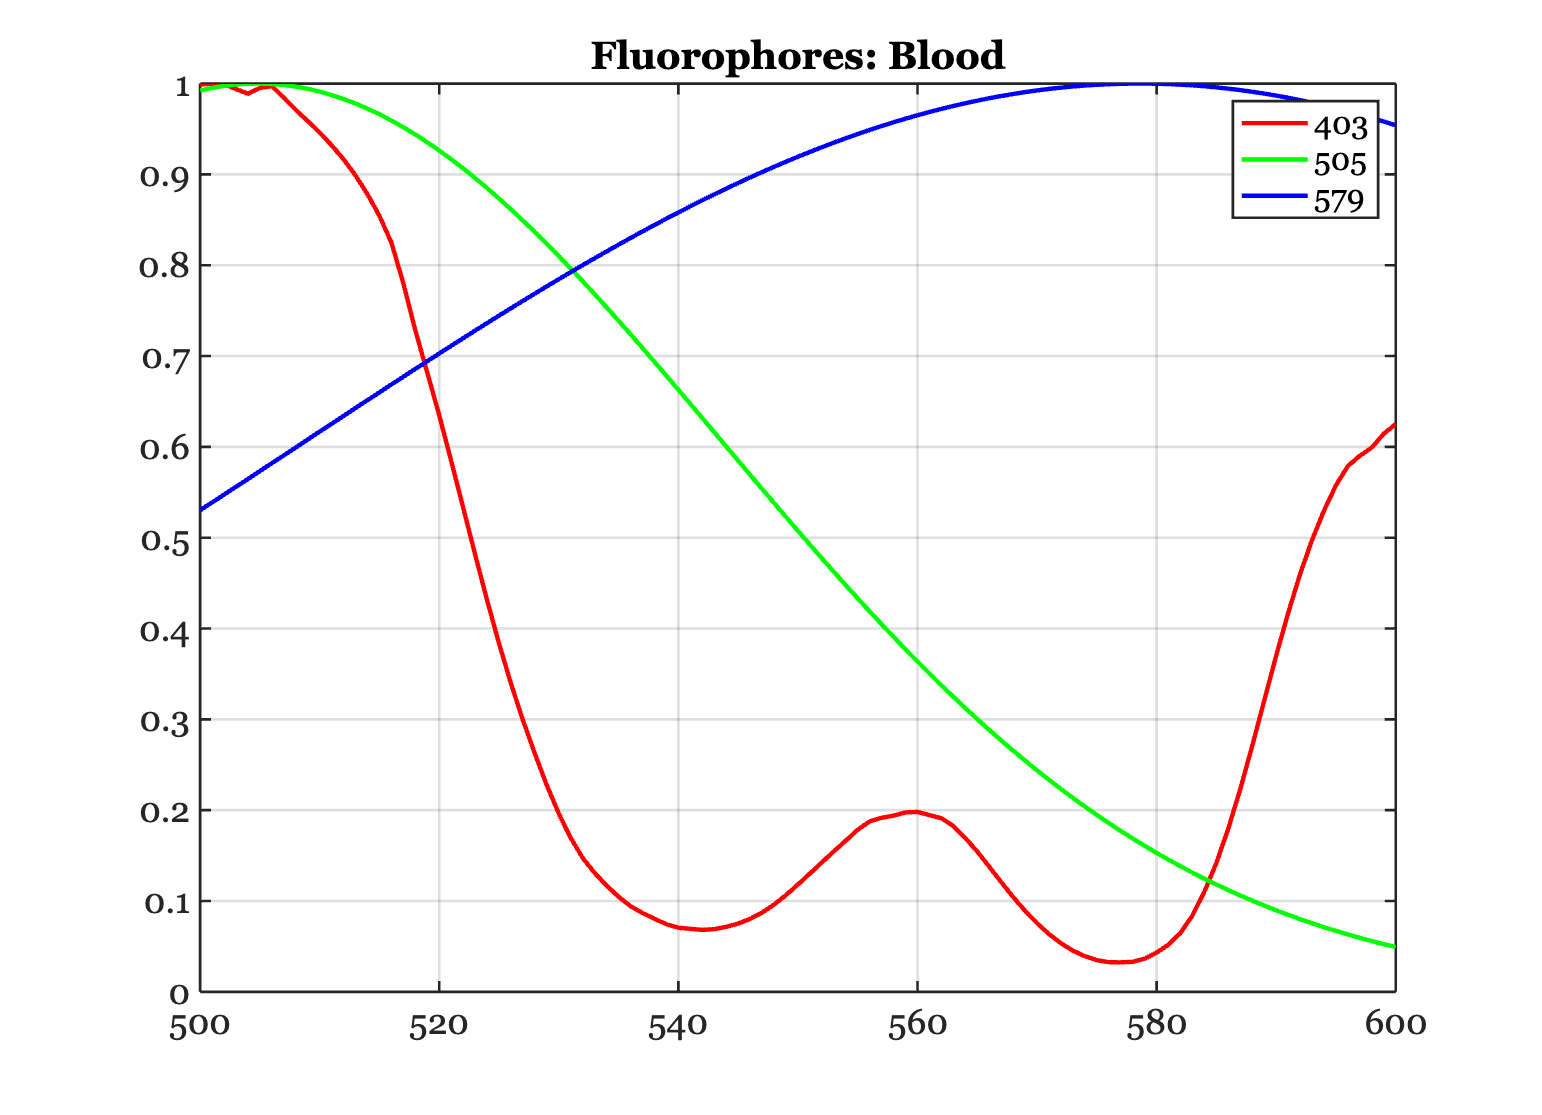


ieFigure;
mx = max(skewedG);
plot(wave,skewedG*diag(1./mx),'LineWidth',2);
title('Fluorophores: Blood');
lgn = legend({num2str(round(global_params(1))),num2str(round(global_params(2))),num2str(round(global_params(3)))});
grid on;

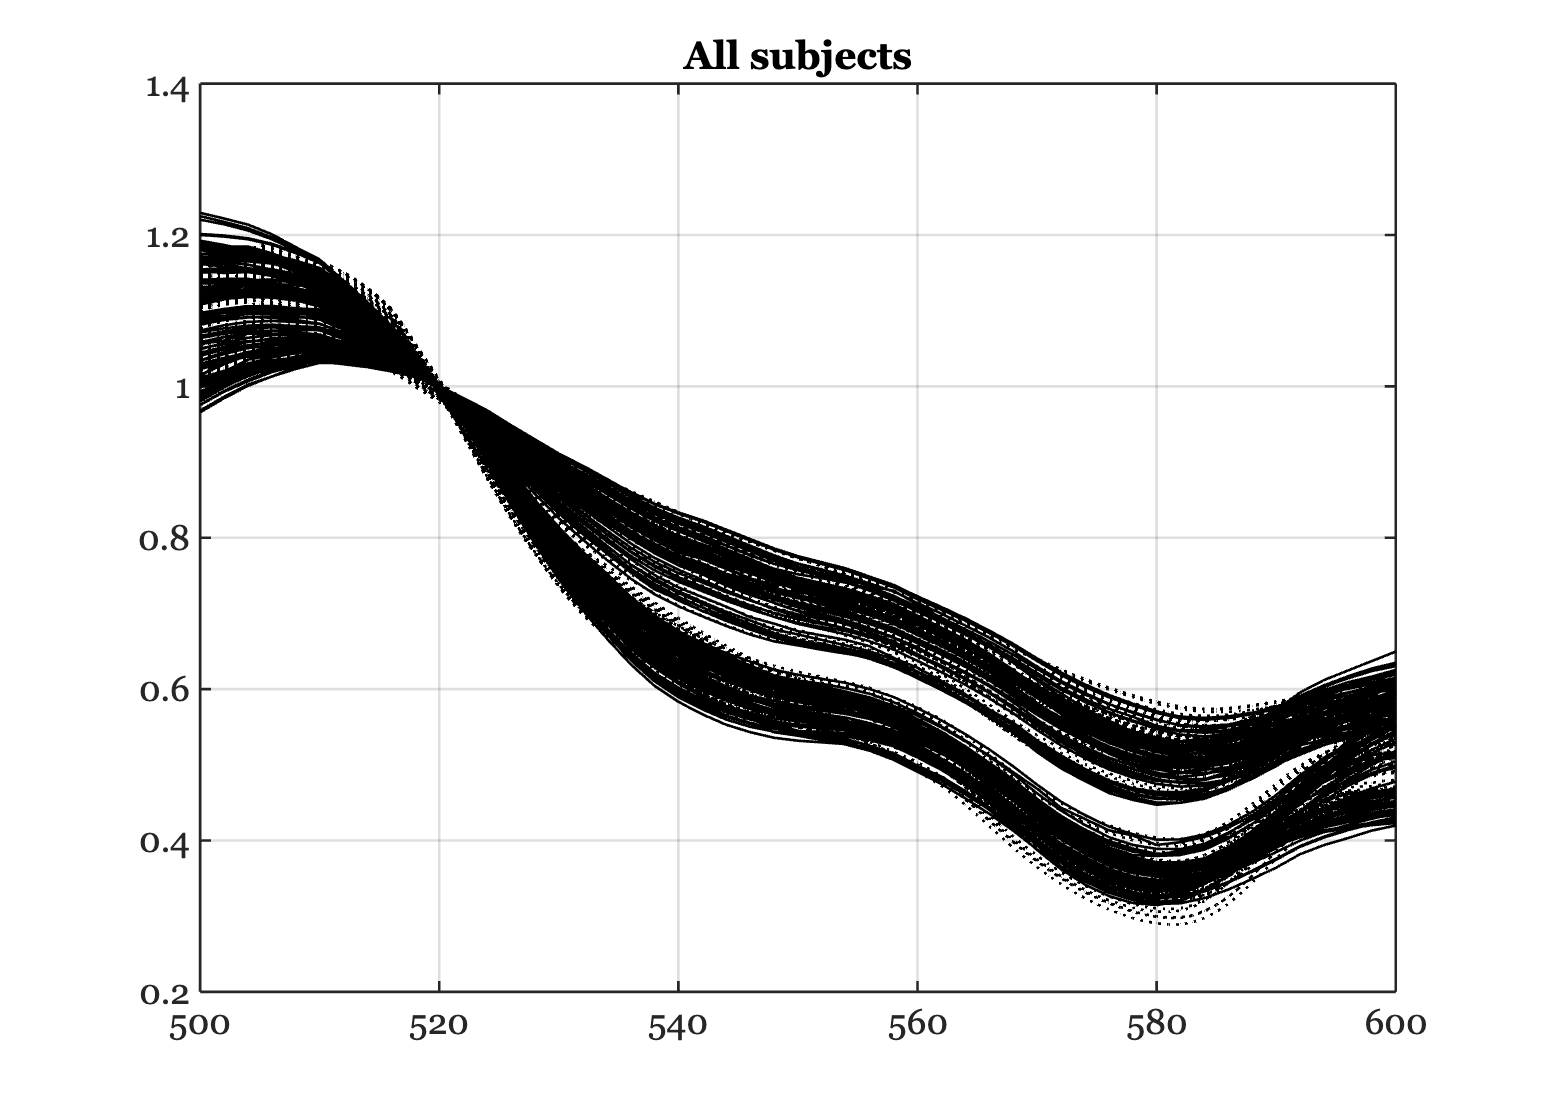


ieFigure;
plot(wave,allData,'k-',wave,skewedG*wgtsNN,'k:');
grid on; title('Fits')
title(sprintf('All subjects'));

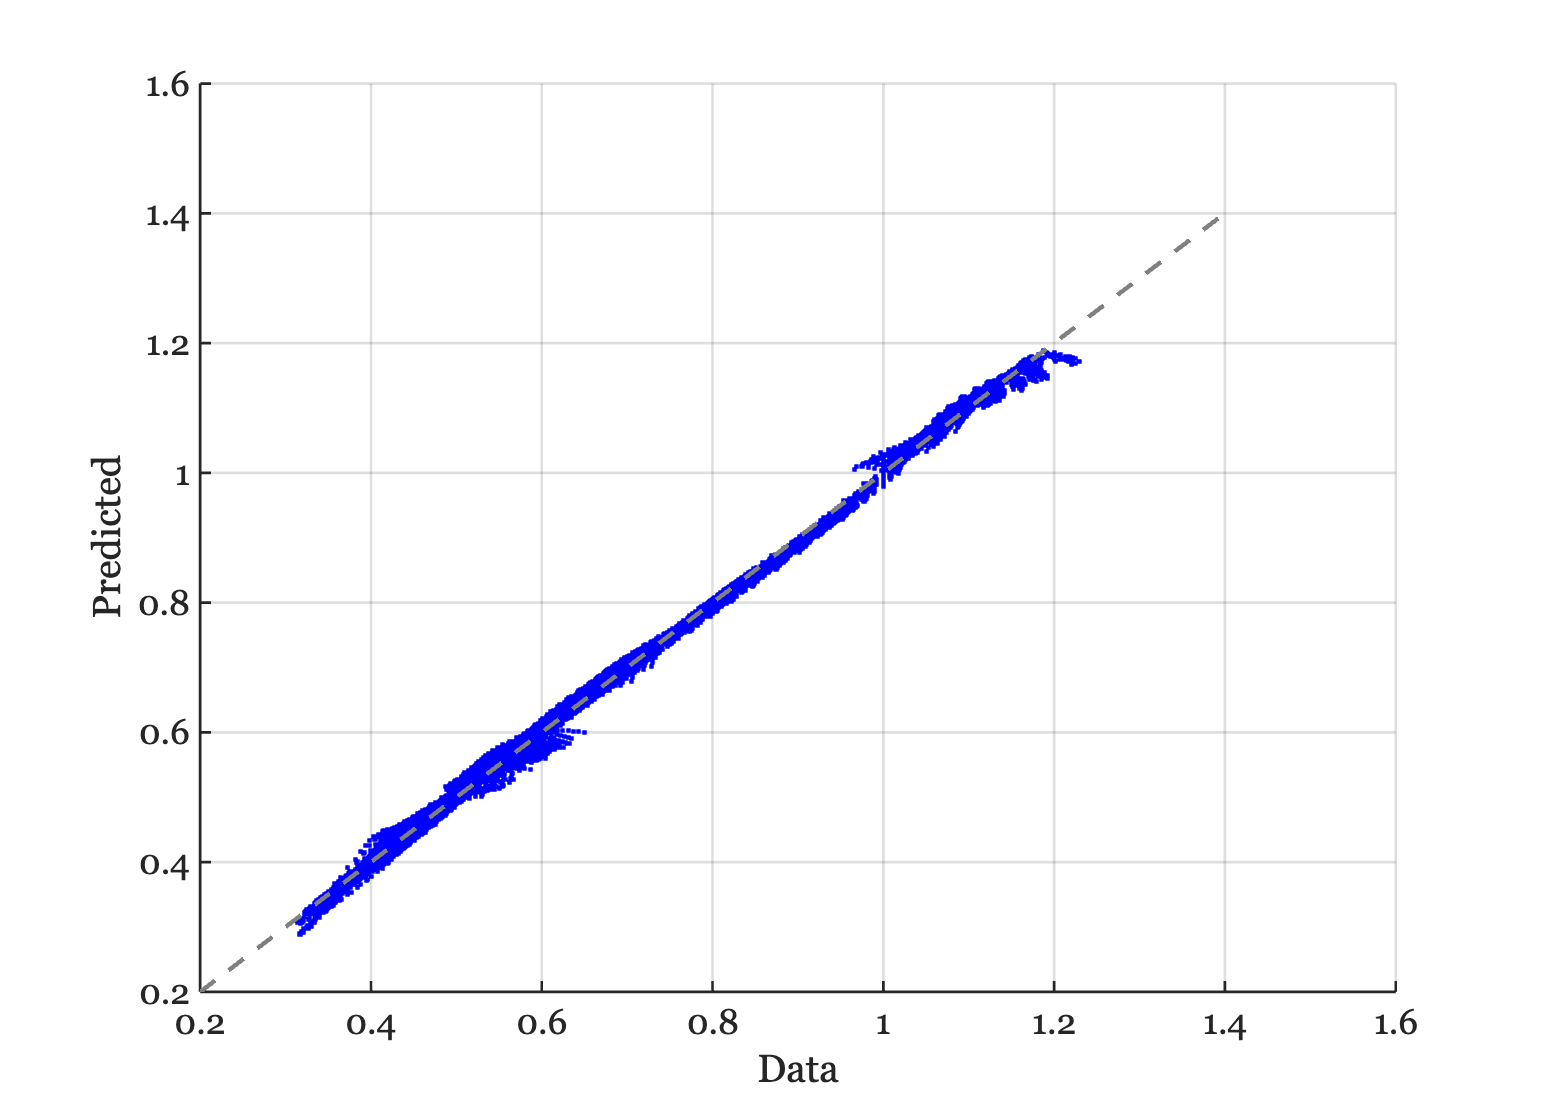


ieFigure;
tmp = skewedG*wgtsNN;
scatter(allData(:),tmp(:),'b.');
identityLine;
grid on;
xlabel('Data'); ylabel('Predicted');

## 3D plot of the weights

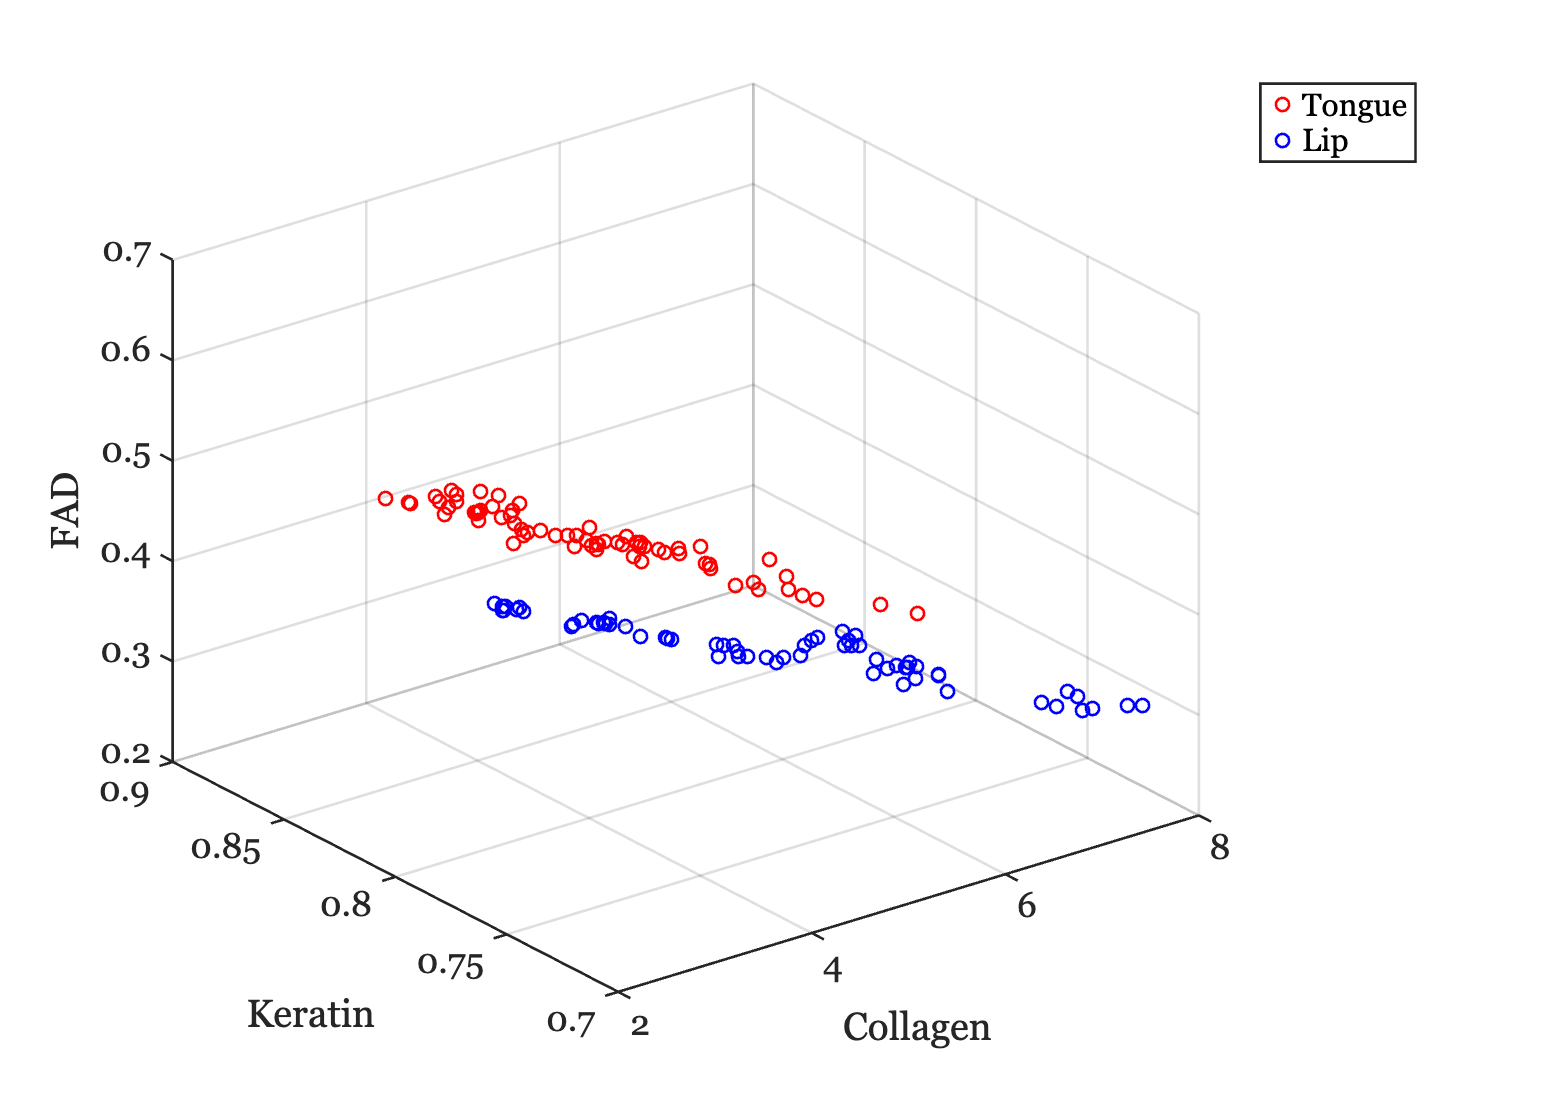

ieFigure;
plot3(tongueWeights(1,:),tongueWeights(2,:),tongueWeights(3,:),'ro');
hold on;
plot3(lipWeights(1,:),lipWeights(2,:),lipWeights(3,:),'bo');
grid on;
xlabel('Collagen'); ylabel('Keratin'); zlabel('FAD');
legend({'Tongue','Lip'});

## Try to fit the lip data using two or three fluorophores

Different blood conditions are implemented.

nFluorophores is (2, 3, or  3.1)

- If 2, the first has blood applied

- If 3, the first two have blood applied

- If 3.1, only the first of the three has blood applied.

Including a 3rd one attenuated by blood does not improve the result.  A 3rd one that is a regular skewed Gaussian does fit better.

nFluorophores = 3.1;

lipData = allData(:,(Tnum+1:end));
%{
oxyblood.opticalDensity = 15;
oxyTransmittance = oxyblood.transmittance;
%}

[global_params, lipWeights, skewedG2] = ...
    oeSolveFluorophoresSkewedGaussiansLip(wave, lipData, ...
    oxyTransmittance,nFluorophores);

disp('Optimized Gaussian Parameters:');

Optimized Gaussian Parameters:


for ii=1:round(nFluorophores)
    fprintf('%d - Peak: %.1f Spread: %.1f Skew: %.1f\n',...
        ii,global_params(ii:round(nFluorophores):end));
end

1 - Peak: 404.0 Spread: 124.8 Skew: -0.0
2 - Peak: 499.1 Spread: 23.0 Skew: -0.0
3 - Peak: 528.3 Spread: 52.4 Skew: -0.1


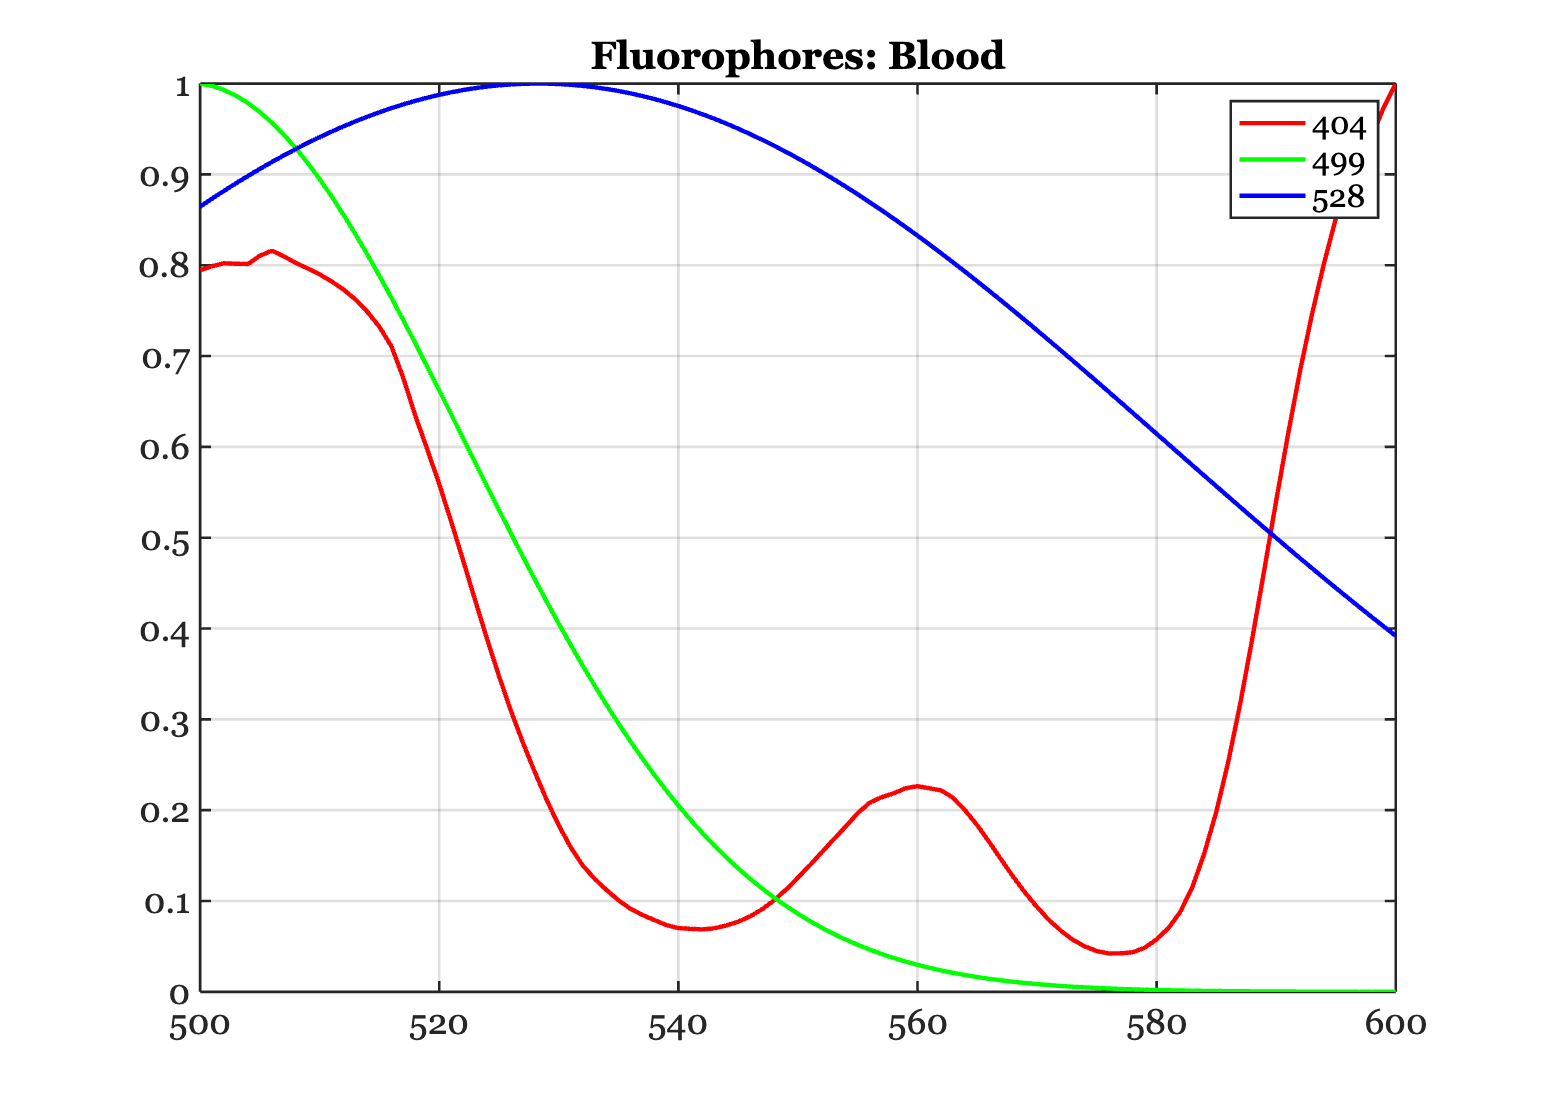


ieFigure;
mx = max(skewedG2);
plot(wave,skewedG2*diag(1./mx),'LineWidth',2);
title('Fluorophores: Blood');
if nFluorophores == 2
lgn = legend({num2str(round(global_params(1))),...
    num2str(round(global_params(2)))});
else
lgn = legend({num2str(round(global_params(1))),...
    num2str(round(global_params(2))), ...
    num2str(round(global_params(3)))});
end

grid on;

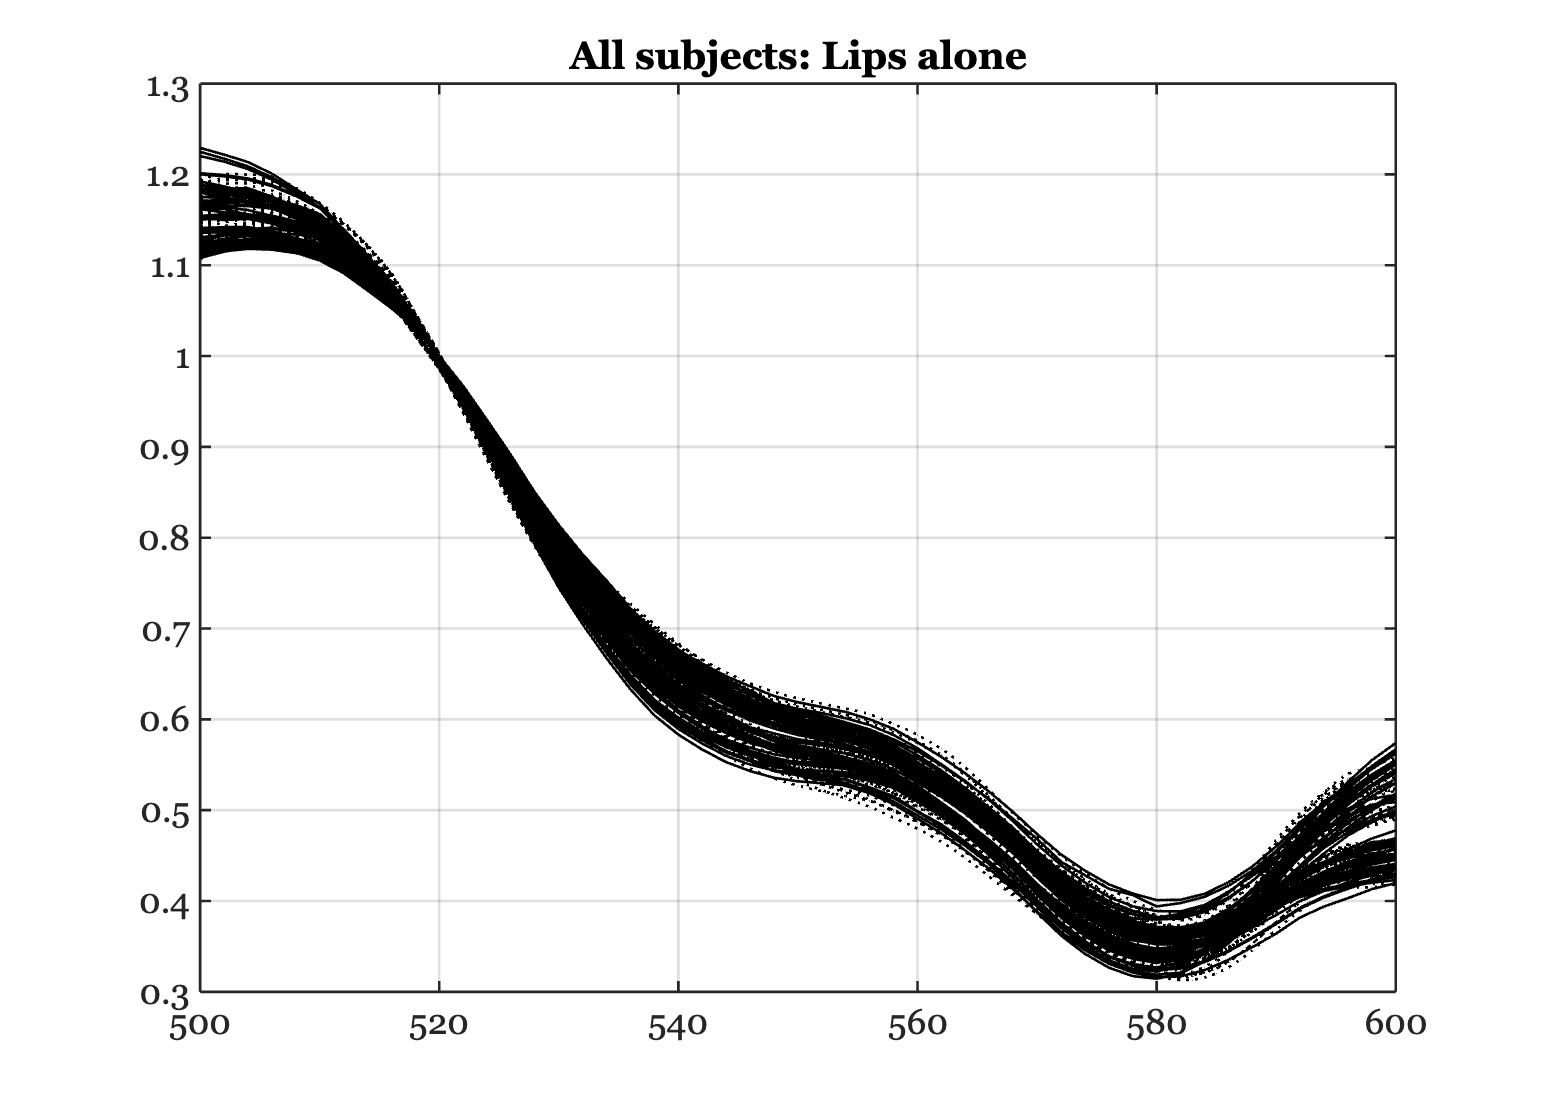


ieFigure;
plot(wave,lipData,'k-',wave,skewedG2*lipWeights,'k:');
grid on; title('Fits')
title(sprintf('All subjects: Lips alone'));

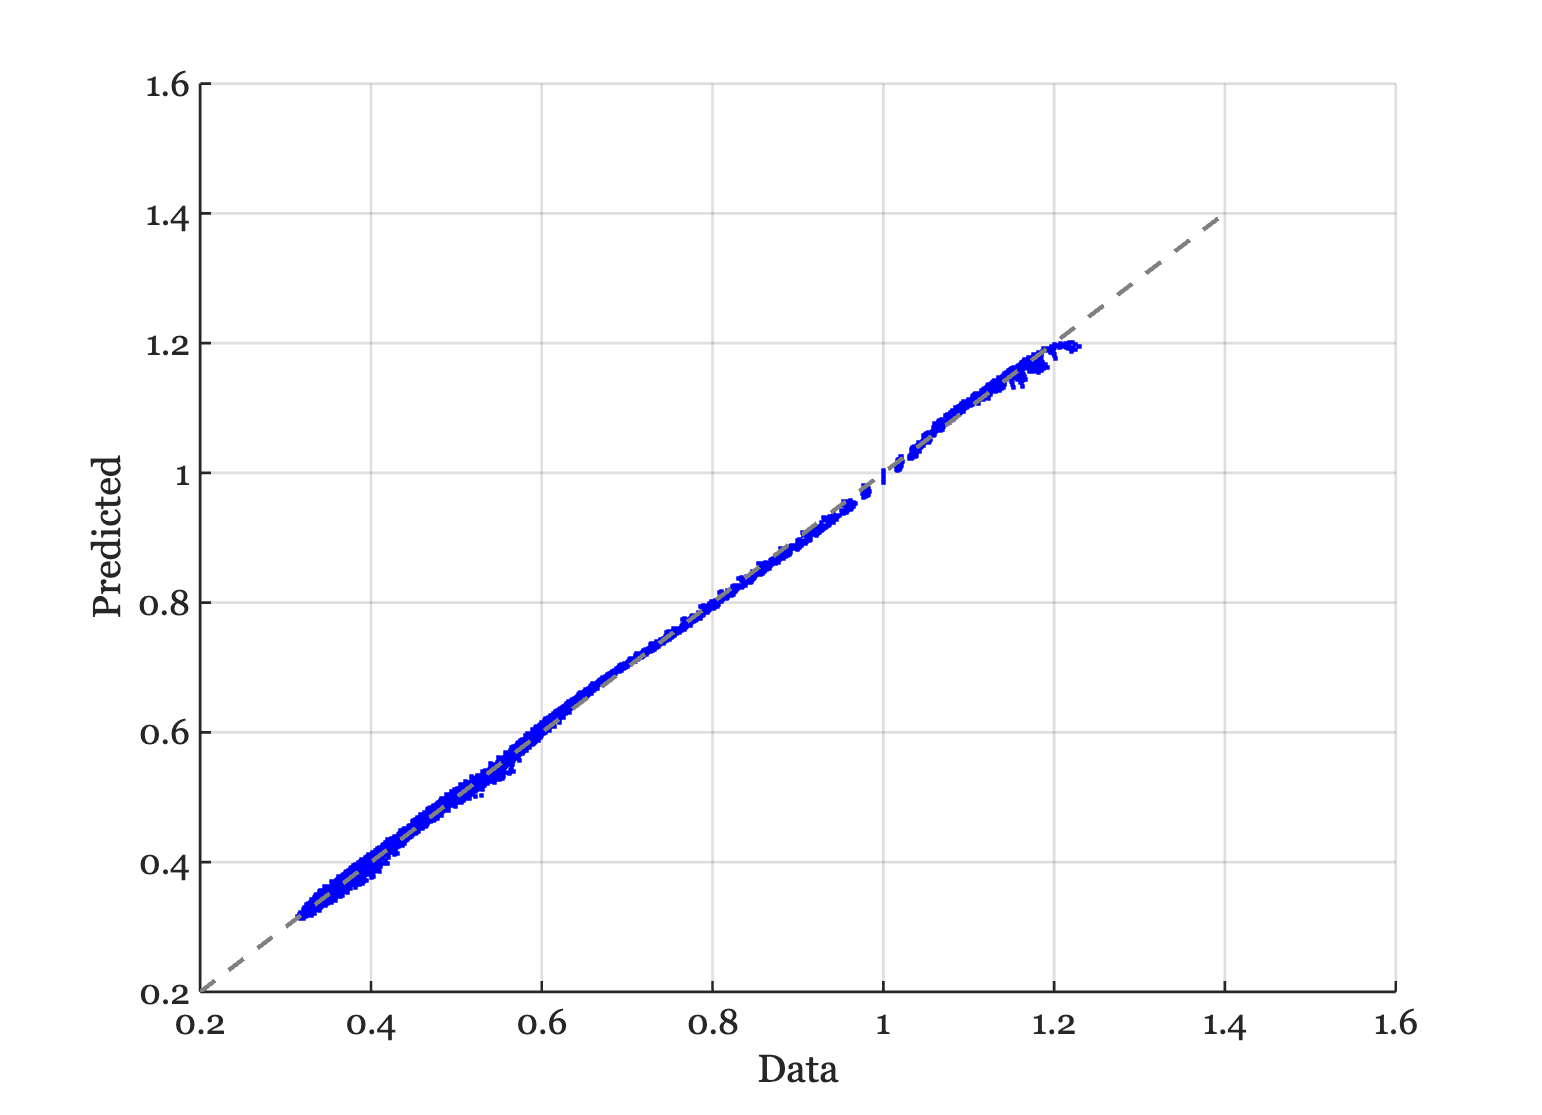


ieFigure;
tmp = skewedG2*lipWeights;
scatter(lipData(:),tmp(:),'b.');
identityLine;
grid on;
xlabel('Data'); ylabel('Predicted');